# Assignment 2

Stephen Cruz Wright

Vladislav Serafimov

## Frequency analysis

[y, fs] = audioread("week2_unknown_guitar_string.wav");
yf = fft(y);
stem(linspace(0,44100, length(abs(yf))) ,abs(yf))

We limit the frequency range to 400 because the high E string of the guitar is tuned to ~329 Hz

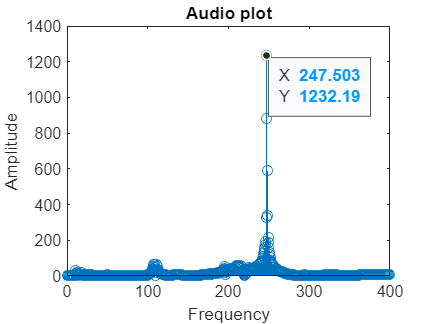

xlim([0, 400])
title("Audio plot")
xlabel("Frequency")
ylabel("Amplitude")

figure

From the plot we can deduce that the frequency is 247,503 Hz, meaning that an open B string is being played.

## Z transform

### 1. 

Using the z-transform $X(z) = \sum{x[n].z^{-n}}$ of $x[n] = \{0,1,2,3,2,7\}$ we can calculate $X(z) = x[1]z^{-1} + x[2] z^{-2}+ x[3]z^{-3} + x[4]z^{-4} + x[5]z^{-5}$


$$ = 
 z^{-1}(1 + 2 z^{-1}+ 3^{-2} + 2z^{-3} + 7z^{-4})
$$


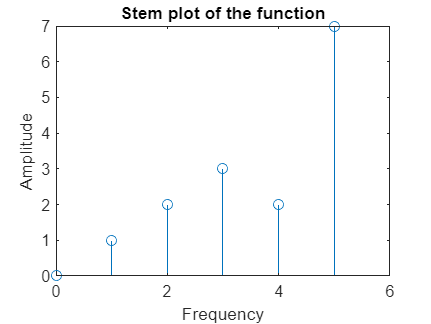

clear
xn = [0, 1, 2, 3, 2, 7];
stem(0:5,xn)
title("Stem plot of the function")
xlim([0, 6])
xlabel("Frequency")
ylabel("Amplitude")

figure

### 2.

Function: $x(t) = 4t - 4te^{-3t}$

#### a)


$$x(0) = -4$$



$$x(1) = 4 - 4e^{-3} \approx 3,8$$



$$x(2) = 8 - 8e^{-6} \approx 7,96$$



$$x(3) = 12 - 12e^{-9} \approx 11,99$$


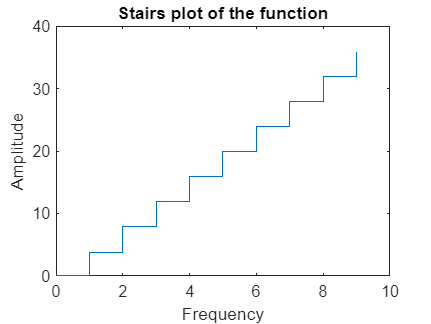

clear
t = 0:9;
xt = 4*t- 4.*t.*exp(-3.*t);
stairs(t, xt)
title("Stairs plot of the function")
xlabel("Frequency")
ylabel("Amplitude")

figure

#### b)


$$X(z) \approx -4 + 3,8z^{-1} + 7,96z^{-2} + 11,99z^{-3}$$


### 3.

####  a)


$$x(t) = 3sin(4t) + 4cos(4t)$$



$$X(z) \approx 4 - 4,885z^{-1} + 2,386z^{-2} + 1,766z^{-3}$$


clear
syms t [1 4];
xt = 3.*sin(4.*t) + 4.*cos(4.*t);
ztrans(simplify(xt))

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \frac{3\,z\,\sin\left(4\right)}{\sigma_{1}}+\frac{4\,z\,\left(z-\cos\left(4\right)\right)}{\sigma_{1}} & \frac{z\,\left(4\,\cos\left(4\,t_{2}\right)+3\,\sin\left(4\,t_{2}\right)\right)}{z-1} & \frac{z\,\left(4\,\cos\left(4\,t_{3}\right)+3\,\sin\left(4\,t_{3}\right)\right)}{z-1} & \frac{z\,\left(4\,\cos\left(4\,t_{4}\right)+3\,\sin\left(4\,t_{4}\right)\right)}{z-1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{2}-2\,\cos\left(4\right)\,z+1 \end{array}$$

#### b)


$$x(k) = 7,4^k$$



$$X(z) \approx 1 + 7,4z^{-1} + 54,76z^{-2} + 405,224z^{-3}$$


clear
syms k [1 4];
xk = 7.4.^k;
ztrans(simplify(xk))

$$ans = \left(\begin{array}{cccc} \frac{z}{z-\frac{37}{5}} & \frac{{\left(\frac{37}{5}\right)}^{k_{2}}\,z}{z-1} & \frac{{\left(\frac{37}{5}\right)}^{k_{3}}\,z}{z-1} & \frac{{\left(\frac{37}{5}\right)}^{k_{4}}\,z}{z-1} \end{array}\right)$$

#### c)


$$x(k) = 7k.7^{k - 1} = k7^k$$



$$X(z) \approx 7z^{-1} + 98z^{-2} + 1029z^{-3}$$


clear
syms k [1 4];
xk = k.*7.^k;
ztrans(simplify(xk))

$$ans = \left(\begin{array}{cccc} \frac{7\,z}{{\left(z-7\right)}^{2}} & \frac{7^{k_{2}}\,k_{2}\,z}{z-1} & \frac{7^{k_{3}}\,k_{3}\,z}{z-1} & \frac{7^{k_{4}}\,k_{4}\,z}{z-1} \end{array}\right)$$

### 4.

 
$$H(s) = \frac{2s + 1}{(s + 1)(s + 2)} = \frac{A}{s + 1} + \frac{B}{s + 2} = \frac{s(A + B) + 1(2A + B)}{(s + 1)(s + 2)}$$


Then $2s + 1 = s(A + B) + (2A + B)$ giving us $A = -1; B = 3$


$$H(s) = \frac{-1}{s + 1} + \frac{3}{s + 2}$$


s = tf('s');
H1 = [2 1];

Lower part is $s(s + 1)(s + 2) = s^3 + 3s^2 + 2s$

H2 = [1 3 2 0];
[r, p, k] = residue(H1, H2);
r

r =    -1.5000
    1.0000
    0.5000


p

p =     -2
    -1
     0
